# **ECG ANALYSIS**

Required Toolboxes

- Signal Processing Toolbox

- pan_tompkin

# Import ECG Data

### 1. Load data

% specify the subject
% subject = input('Subject: '); 
subject = 1; % Use the data from subject 1 for this final project

% load .mat file with the arrray 'ecg_data' inside
ecg_data = load(sprintf("dataset/ecg_Subject%d.mat", subject));
ecg_data = ecg_data.ecg_data;

% sampling rate (Hz)
fs = 512;
numSamples = numel(ecg_data);

### 2. Filter

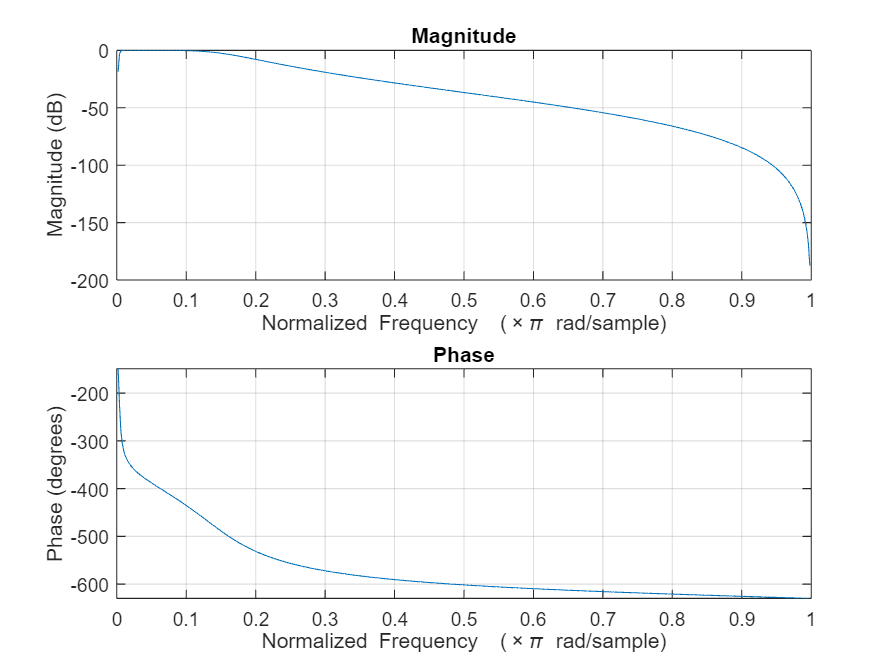

% Filter order
order = 3;

% Cutoff frequencies (in Hz)
low_freq = 1;
high_freq = 40;

% Calculate normalized cutoff frequencies
Wn = [low_freq, high_freq] / (fs/2);

%% Create Filters
[b, a] = butter(order, Wn, 'bandpass'); % Bandpass Filter
[d, c] = butter(order ,[0.37 0.41],'stop'); % Notch Filter


freqz(b,a) % check frequency and phase response of the filter


ecg_filter = filtfilt(b, a, reshape(ecg_data,[1,numSamples]));

### 3. R-peak detection

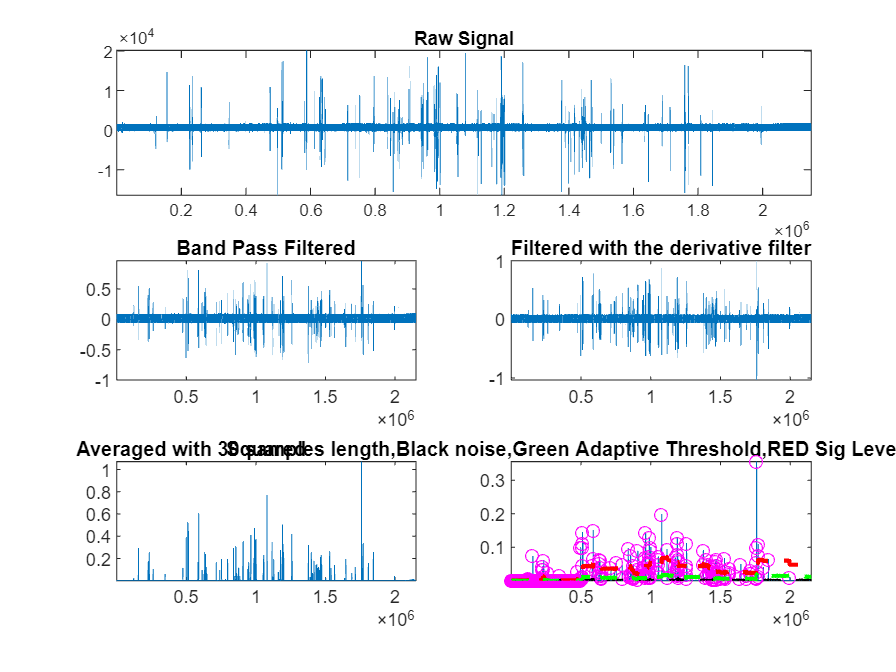

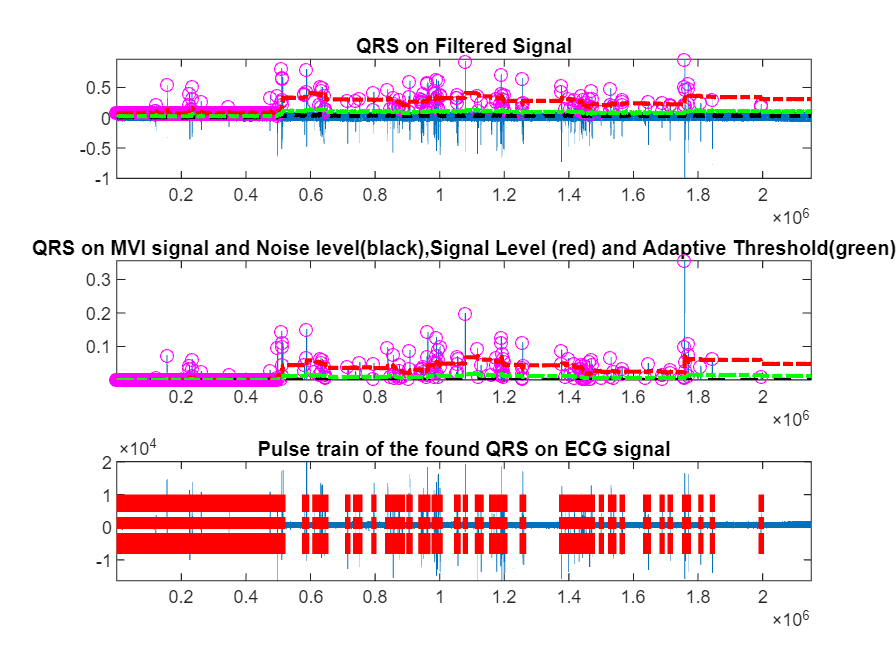

qrs_amp_raw =     0.0803    0.0840    0.0842    0.0820    0.0811    0.0798    0.0819    0.0849    0.0841    0.0842    0.0833    0.0818    0.0817    0.0839    0.0828    0.0847    0.0858    0.0836    0.0841    0.0814    0.0829    0.0827    0.0817    0.0799    0.0812    0.0807    0.0793    0.0789    0.0789    0.0798    0.0810    0.0797    0.0796    0.0786    0.0788    0.0815    0.0806    0.0806    0.0792    0.0786    0.0786    0.0758    0.0876    0.0812    0.0835    0.0823    0.0819    0.0821    0.0763    0.0817


qrs_i_raw =           69         402         734        1072        1414        1758        2098        2434        2774        3125        3478        3839        4189        4525        4854        5178        5507        5844        6193        6543        6909        7274        7637        7995        8341        8690        9038        9387        9734       10072       10410       10748       11086       11424       11756       12085       12413       12733       13046       13356       13667       13981       14298       14611       14928       15250       15578       15921       16272       16616


delay = 38.5000

[qrs_amp_raw,qrs_i_raw,delay] = pan_tompkin(ecg_filter, fs, 1)


rpeak_time = qrs_i_raw / fs;

rpeak_amp = ecg_filter(qrs_i_raw + 1)

rpeak_amp = 1.0e+04 *

    0.1355    0.1475    0.1484    0.1441    0.1436    0.1416    0.1437    0.1461    0.1475    0.1496    0.1511    0.1434    0.1449    0.1485    0.1309    0.1462    0.1471    0.1441    0.1453    0.1449    0.1422    0.1400    0.1442    0.1425    0.1408    0.1395    0.1381    0.1372    0.1387    0.1415    0.1454    0.1413    0.1396    0.1350    0.1408    0.1425    0.1441    0.1464    0.1406    0.1390    0.1368    0.1228    0.1305    0.1363    0.1492    0.1449    0.1473    0.1353    0.1466    0.1266


### 4. Calculate RRI

rri_index = diff(qrs_i_raw) / fs; % Convert sample indices to seconds
rri_time = (diff(rpeak_time))';

### 5. Plotting Tachogram

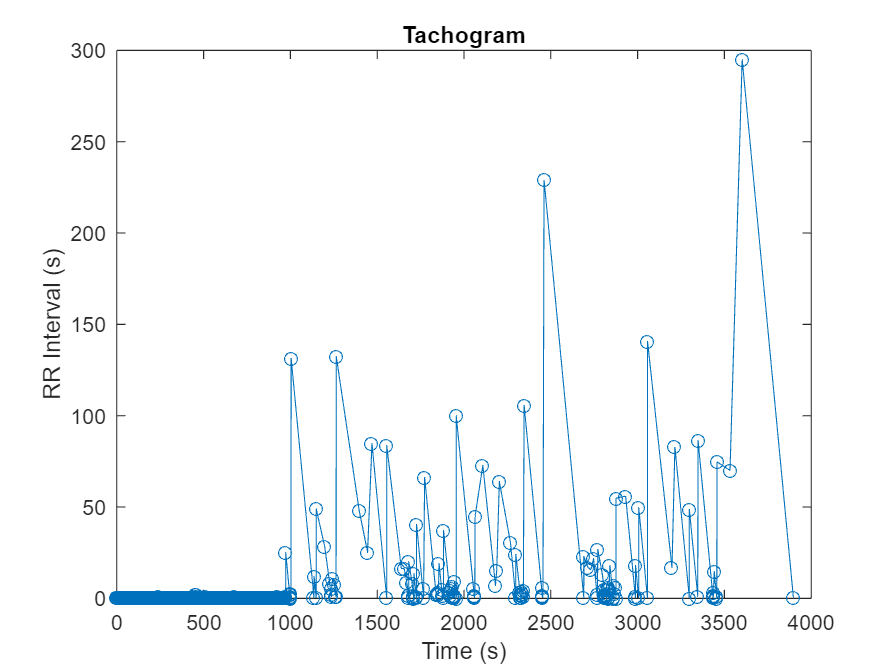

% Assuming rriArray contains RR intervals in seconds

% Cumulative sum to get timestamps for each RRI (excluding the first interval at time 0)
rri_timestamps = cumsum([0; rri_time(1:end-1)]);

% Plot the tachogram: RR intervals over time
figure;
plot(rri_timestamps, rri_time, 'o-');
xlabel('Time (s)');
ylabel('RR Interval (s)');
% xlim([0 20])
title('Tachogram');

# Manage the Large Artifacts

### a. Amplitude Detection

threshold = mean(rpeak_amp) + 500;
highAmplitudeIndices = find(abs(ecg_filter) > threshold);

### b. Reduce the Amplitude

% Set to 2000 (or -2000 depending on the sign)
ecg_reduceAmp = ecg_filter;
ecg_reduceAmp(highAmplitudeIndices) = 0 .* sign(ecg_reduceAmp(highAmplitudeIndices));

### c. Re-apply R-peak Detection

**variable:** rpeak_time_reduceAmp

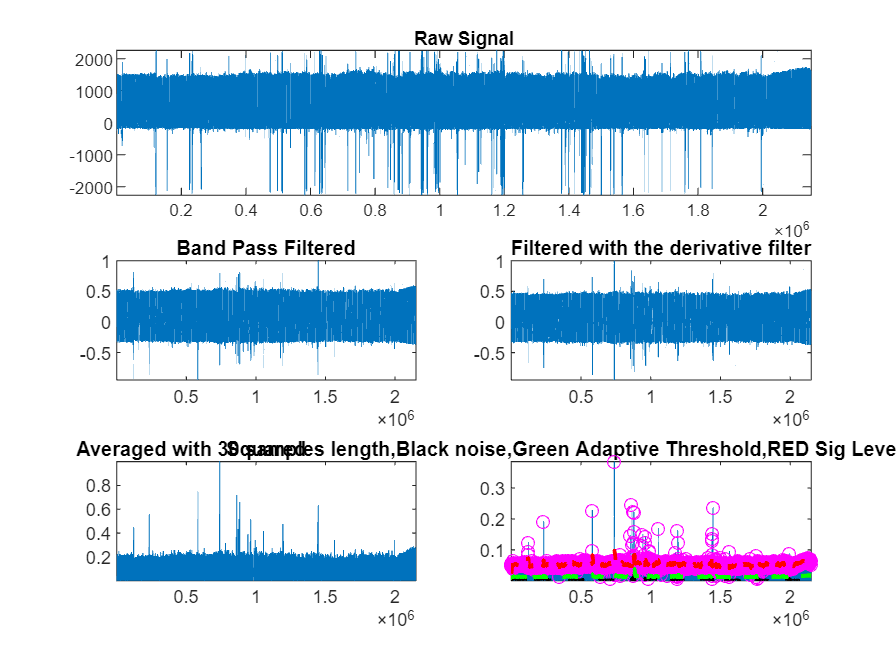

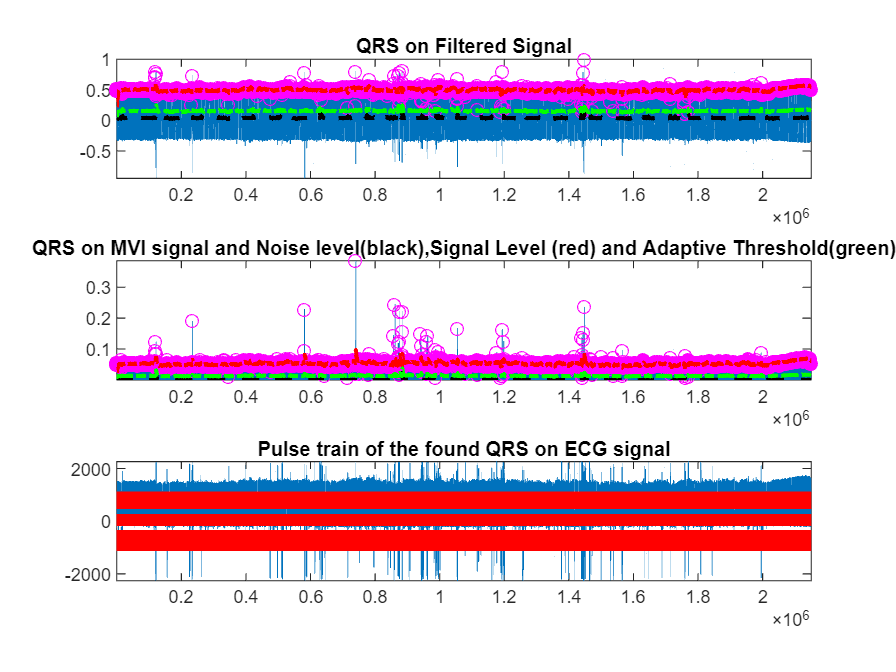

qrs_amp_reduceAmp =     0.4937    0.5163    0.5178    0.5040    0.4984    0.4904    0.5037    0.5217    0.5168    0.5179    0.5123    0.5026    0.5026    0.5155    0.5090    0.5205    0.5274    0.5141    0.5171    0.5002    0.5096    0.5083    0.5021    0.4911    0.4992    0.4960    0.4877    0.4851    0.4849    0.4906    0.4977    0.4902    0.4891    0.4834    0.4843    0.5012    0.4957    0.4954    0.4868    0.4834    0.4833    0.4658    0.5383    0.4991    0.5136    0.5062    0.5037    0.5048    0.4691    0.5023


qrs_i_reduceAmp =           69         402         734        1072        1414        1758        2098        2434        2774        3125        3478        3839        4189        4525        4854        5178        5507        5844        6193        6543        6909        7274        7637        7995        8341        8690        9038        9387        9734       10072       10410       10748       11086       11424       11756       12085       12413       12733       13046       13356       13667       13981       14298       14611       14928       15250       15578       15921       16272       16616


delay_reduceAmp = 38.5000

[qrs_amp_reduceAmp,qrs_i_reduceAmp,delay_reduceAmp] = pan_tompkin(ecg_reduceAmp, fs, 1)


rpeak_time_reduceAmp = qrs_i_reduceAmp / fs;

### d. RRI Calculation & Tachogram Plotting

**variable:** rri_reduceAmp

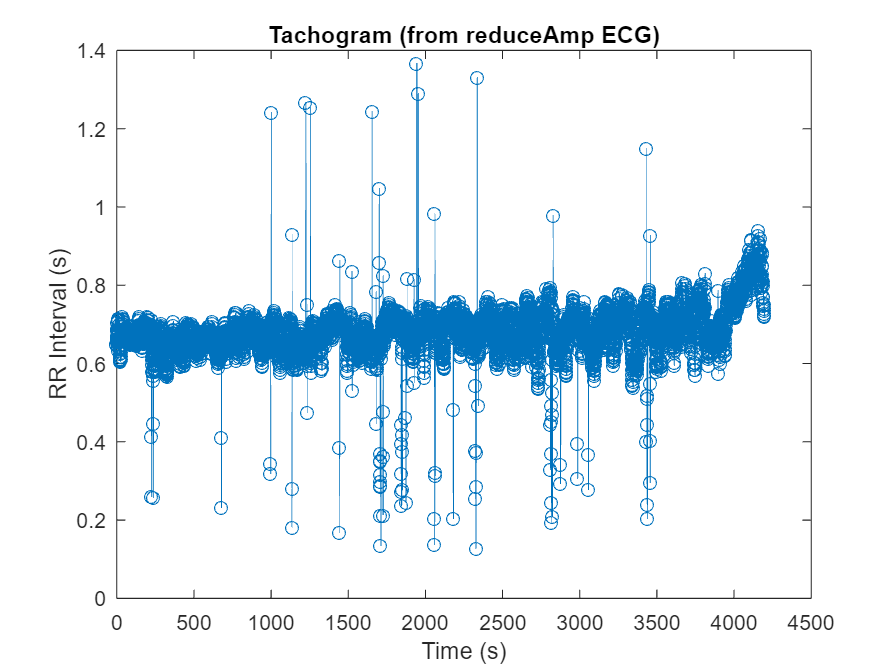

% Convert sample indices to seconds
rri_reduceAmp = (diff(rpeak_time_reduceAmp))';
rri_timestamps_reduceAmp = cumsum([0; rri_reduceAmp(1:end-1)]);

% Plot the tachogram: RR intervals over time
figure;
plot(rri_timestamps_reduceAmp, rri_reduceAmp, 'o-');
xlabel('Time (s)');
ylabel('RR Interval (s)');
% xlim([0 20])
title('Tachogram (from reduceAmp ECG)');

# R-Peak Correction

#### 1. Correct R-peak timestamps

**variable:** correctedRpeakTimestamps

filePath_wrongRpeaks = "dataset/wrongRpeaks.xlsx";

% The function 'RpeakCorrection' is defined at the end of this .mlx file,
% To correct the wrong R-peak detection by pan tompkins algorithm
correct_rpeak_time = RpeakCorrection(rpeak_time_reduceAmp, filePath_wrongRpeaks, subject);

#### 2. Calculate Corrected RRI & Plot Tachogram

**variable:** rri_corrected

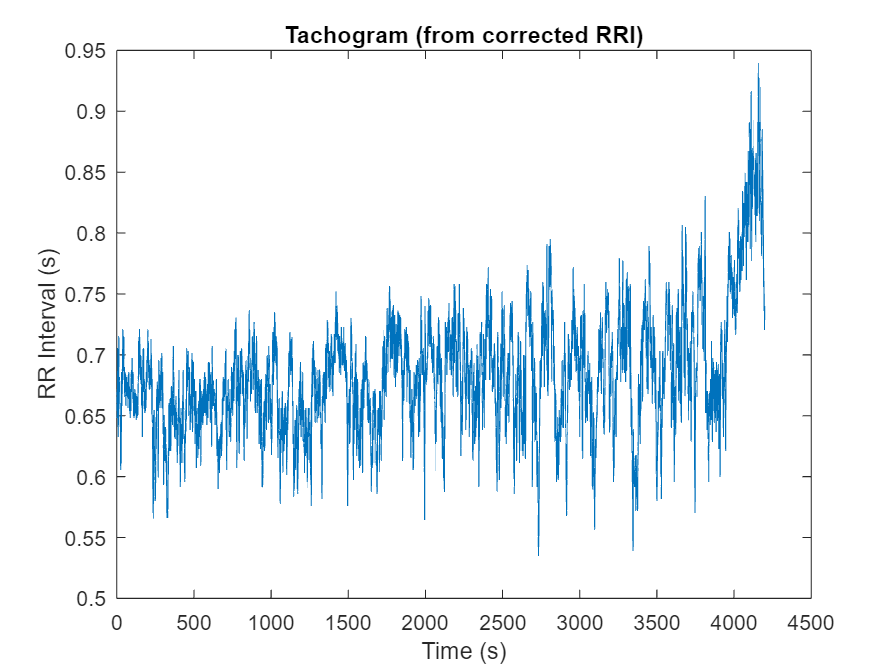

% Convert sample indices to seconds
rri_corrected = (diff(correct_rpeak_time))';
rri_timestamps_corrected = cumsum([0; rri_corrected(1:end-1)]);

% Plot the tachogram: RR intervals over time
figure;
plot(rri_timestamps_corrected, rri_corrected);
xlabel('Time (s)');
ylabel('RR Interval (s)');
% xlim([0 60])
title('Tachogram (from corrected RRI)');

# HRV Feature Extraction

#### 1. Split Epoch and Extract Frequency-domain HRV features

**struct: **EpochDataHRV_corrected

% Define epoch length in seconds (e.g., 5 minutes)
% epochLength = 2 * 60; 
% overlap = 0.75 * epochLength; % Overlap in seconds
epochLength = 60; 
overlap = 0.5 * epochLength; % Overlap in seconds

% Determine the step size for each epoch (epoch length - overlap)
stepSize = epochLength - overlap;

% Determine the total time and number of epochs (adjusted for overlap)
totalTime = rri_timestamps_corrected(end);
% Adjusted calculation for the number of epochs considering the overlap
numEpochs = 1 + floor((length(ecg_data)/fs - epochLength) / stepSize);

% Initialize the structured array to store all epoch data and features
EpochDataHRV_corrected = repmat(struct('Index', [], 'ECG', [], 'ECGTimestamps', [], ...
    'RRI', [], 'RRITimestamps', [], 'VLF', [], 'LF', [], 'HF', [], 'LFHF', []), ...
    numEpochs, 1);

% Sampling frequency for interpolation
interpolate_fs = 4; % Hz, common choice for HRV analysis

% Loop through each epoch, adjusted for overlap
for i = 1:numEpochs

    % Calculate the start time for the current epoch, considering the overlap
    epochStart = rri_timestamps_corrected(1) + (i-1) * stepSize;
    epochEnd = epochStart + epochLength;

    % Segment ECG data
    % Convert epoch start and end times to ECG signal indices
    startIndexECG = floor(epochStart * fs) + 1;
    endIndexECG = min(length(ecg_filter), floor(epochEnd * fs)); % Ensure not to exceed the ECG data length
    EpochDataHRV_corrected(i).ECG = ecg_filter(startIndexECG:endIndexECG);
    EpochDataHRV_corrected(i).ECGTimestamps = (startIndexECG:endIndexECG) / fs;

    % Segment RRI data
    epochIndicesRRI = rri_timestamps_corrected >= epochStart & rri_timestamps_corrected < epochEnd;
    EpochDataHRV_corrected(i).RRI = rri_corrected(epochIndicesRRI);
    EpochDataHRV_corrected(i).RRITimestamps = rri_timestamps_corrected(epochIndicesRRI);
   
    % Segment R-Peaks Detection
    epochIndicesRPeak = correct_rpeak_time >= epochStart & correct_rpeak_time < epochEnd;
    EpochDataHRV_corrected(i).RPeakTimestamps = correct_rpeak_time(epochIndicesRPeak);

    
    % Skip the epoch if there are too few data points
    if length(EpochDataHRV_corrected(i).RRI) < 2
        continue;
    end
    
    % % Interpolate RRI data to get evenly spaced samples
    % epoch_t_interp = epochStart:1/interpolate_fs:epochEnd; % Target sample times
    % epoch_rri_interp = interp1(EpochDataHRV_corrected(i).RRITimestamps, EpochDataHRV_corrected(i).RRI, epoch_t_interp, 'linear', 'extrap');

    % Calculate and store PSD and HRV features directly
    [pLF,pHF,LFHFratio,VLF,LF,HF,f,Y,NFFT] = HRV.fft_val_fun(EpochDataHRV_corrected(i).RRI, interpolate_fs, 'linear');
    EpochDataHRV_corrected(i).VLF = VLF;
    EpochDataHRV_corrected(i).LF = LF;
    EpochDataHRV_corrected(i).HF = HF;
    EpochDataHRV_corrected(i).pLF = pLF;
    EpochDataHRV_corrected(i).pHF = pHF;
    EpochDataHRV_corrected(i).LFHF = LFHFratio;

    % Assign index
    EpochDataHRV_corrected(i).Index = i;

end

EpochDataHRV_corrected

EpochDataHRV_corrected = 139×1 struct array with fields:
    Index
    ECG
    ECGTimestamps
    RRI
    RRITimestamps
    VLF
    LF
    HF
    LFHF
    RPeakTimestamps
    pLF
    pHF


#### 2. [Plot] *Frequency-Domain Features (HRV)* over *Epochs*

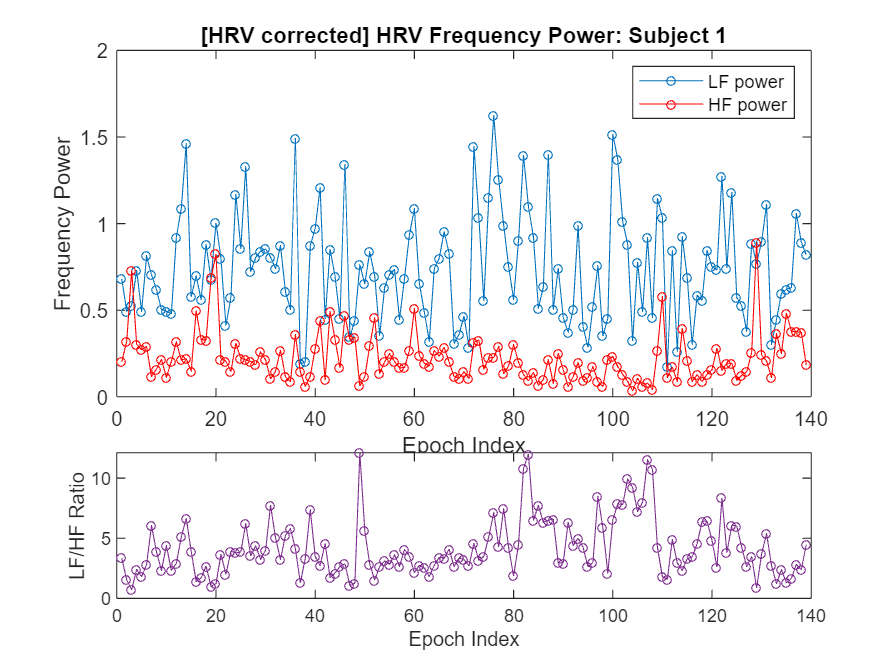

figure;

% LF, HF power plot
subplot(3,1,[1,2]);
plot([EpochDataHRV_corrected.Index], [EpochDataHRV_corrected.LF], 'o-', 'MarkerSize', 4, 'DisplayName', 'LF power');

hold on
plot([EpochDataHRV_corrected.Index], [EpochDataHRV_corrected.HF], 'o-', 'MarkerSize', 4, 'Color', 'r', 'DisplayName', 'HF power');

legend

xlabel('Epoch Index');
ylabel('Frequency Power');
% xlim([ECGEpochs_timestamps{epoch_index}(1) ECGEpochs_timestamps{epoch_index}(5120)])
% ylim([-1000 1000])
title(sprintf('[HRV corrected] HRV Frequency Power: Subject %d', subject));


% LF/HF ratio plot
subplot(3,1,3);
plot([EpochDataHRV_corrected.Index], [EpochDataHRV_corrected.LFHF], 'o-', 'MarkerSize', 4, 'Color', "#7E2F8E");
xlabel('Epoch Index');
ylabel('LF/HF Ratio');

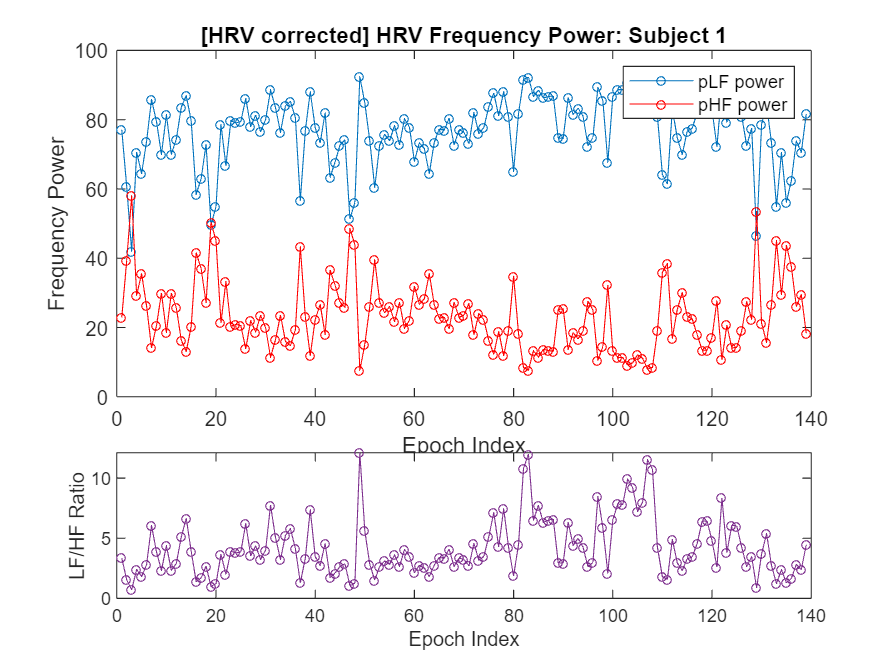

figure;

% LF, HF power plot
subplot(3,1,[1,2]);
plot([EpochDataHRV_corrected.Index], [EpochDataHRV_corrected.pLF], 'o-', 'MarkerSize', 4, 'DisplayName', 'pLF power');

hold on
plot([EpochDataHRV_corrected.Index], [EpochDataHRV_corrected.pHF], 'o-', 'MarkerSize', 4, 'Color', 'r', 'DisplayName', 'pHF power');

legend

xlabel('Epoch Index');
ylabel('Frequency Power');
% xlim([ECGEpochs_timestamps{epoch_index}(1) ECGEpochs_timestamps{epoch_index}(5120)])
% ylim([-1000 1000])
title(sprintf('[HRV corrected] HRV Frequency Power: Subject %d', subject));


% LF/HF ratio plot
subplot(3,1,3);
plot([EpochDataHRV_corrected.Index], [EpochDataHRV_corrected.LFHF], 'o-', 'MarkerSize', 4, 'Color', "#7E2F8E");
xlabel('Epoch Index');
ylabel('LF/HF Ratio');

#### 4. Plot ECG data of the specific epoch

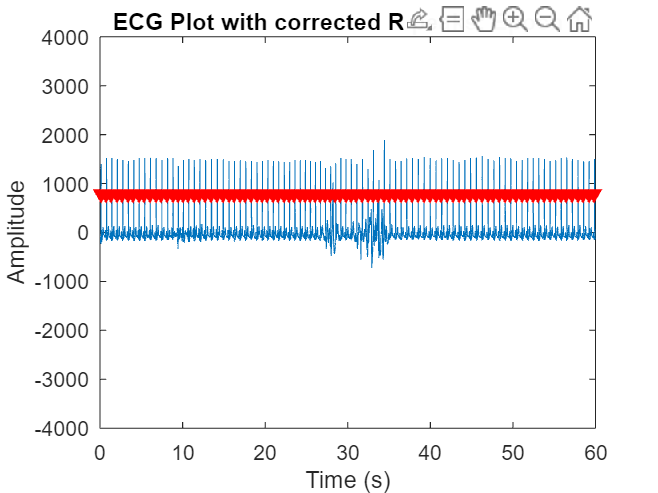

epoch_index = input('epoch index: ');

figure;
plot(EpochDataHRV_corrected(epoch_index).ECGTimestamps, EpochDataHRV_corrected(epoch_index).ECG);
hold on
scatter(EpochDataHRV_corrected(epoch_index).RPeakTimestamps, 800, 'filled', 'v', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');

epochIndicesRRI = rri_timestamps_corrected >= epochStart & rri_timestamps_corrected < epochEnd;

xlabel('Time (s)');
ylabel('Amplitude');
%xlim([EpochData(epoch_index).ECGTimestamps(1) EpochData(epoch_index).ECGTimestamps(5120)])
ylim([-4000 4000])

title(sprintf('ECG Plot with corrected R peaks: Epoch %d', epoch_index));

# **EEG ANALYSIS**

# EEG Preprocessing

## 1. Load Data 

*eeg_raw*: contains data of 12 eeg channels

% subject = input('Subject: '); 
subject = 1; % use the data from subject 1 for this final project

channelName = {'O1', 'O2', 'Fp1', 'Fp2', 'P7', 'P8', ...
               'P3', 'P4', 'F3', 'F4', 'T7', 'T8'};

fs = 512; % Sampling rate (Hz)

% load .mat file with the arrray 'eeg_raw_crop' inside
eeg_raw = load(sprintf("dataset/eeg_Subject%d.mat", subject));
eeg_raw = eeg_raw.eeg_raw_crop;

## 3. Filter

**Lowpass Filter: *****eeg_lowpass***

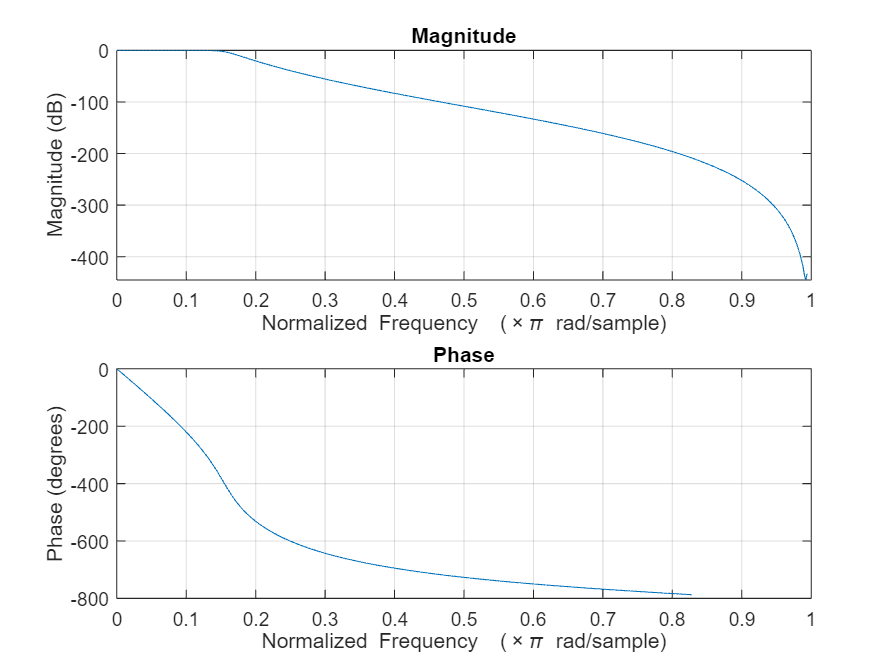

%% Low Pass Filter 
% Order
lowpass_order = 9;
    
% Cutoff frequencies (Hz)
lowpass_freq = 40;

% Calculate normalized cutoff frequencies
lowpass_Wn = lowpass_freq / (fs/2);

% Design lowpass Butterworth filter
[x, y] = butter(lowpass_order, lowpass_Wn, 'Low');

freqz(x, y)


eeg_lowpass = filtfilt(x, y, eeg_raw);

**Highpass Filter: *****eeg_lowhighpass***

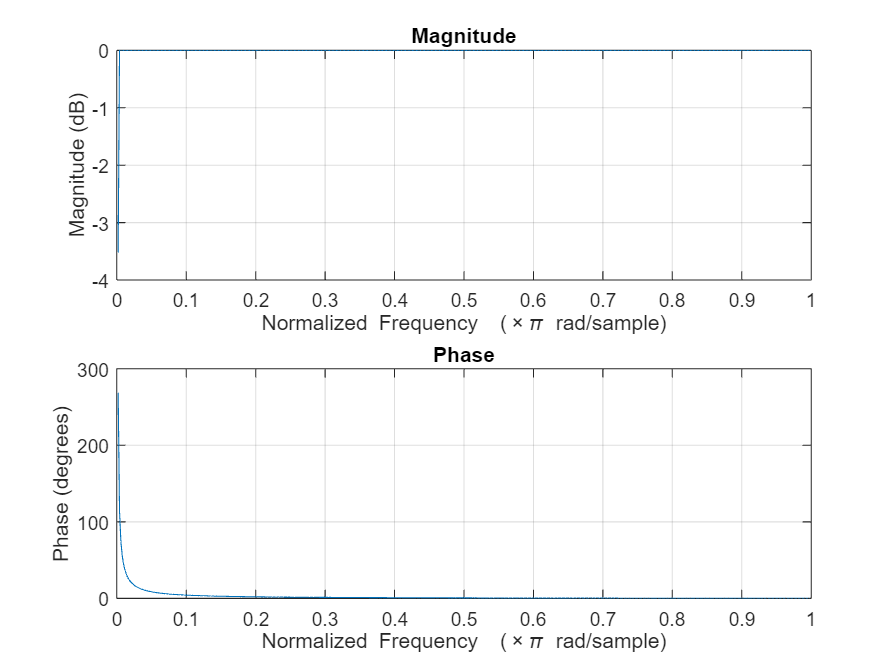

%% High Pass Filter

% Order
highpass_order = 6;

% Cutoff frequencies (Hz)
highpass_freq = 0.5;

% Calculate normalized cutoff frequencies
highpass_Wn = highpass_freq / (fs/2);

% Design lowpass Butterworth filter
[w, z] = butter(highpass_order, highpass_Wn, 'High');

freqz(w, z)


eeg_lowhighpass = filtfilt(w, z, eeg_lowpass);

# EEG Feature Extraction

## [[ Frequency Domain Feature Extraction ]]

- method for PSD Estimate: *Welch's method*

- 6 features: 1) Relative Delta Power, 2) Relative Theta Power, 3) Relative Alpha Power, 4) Relative Beta Power, 5) Alpha/Beta Ratio, 6) (Theta+Alpha)/Beta Ratio

### 📌 Define Frequency Bands

FreqTotal = [0.5 40];
FreqDelta = [0.5 4];
FreqTheta = [4 8];
FreqAlpha = [8 12];
FreqBeta = [12 30];
FreqGamma = [30 40];

### 📌 Calculate Frequency Domain Power for all *Channels* and all *Epochs*

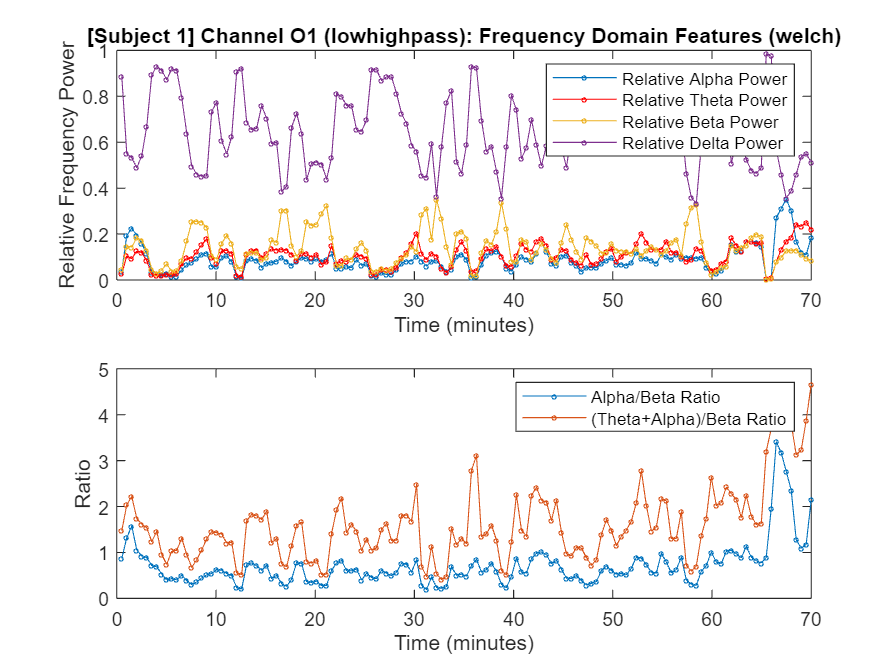

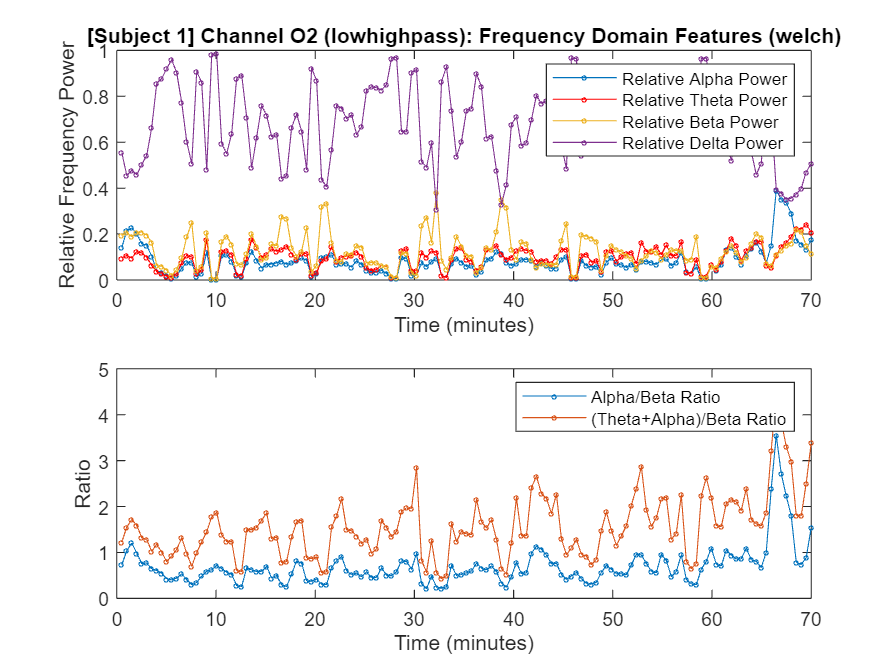

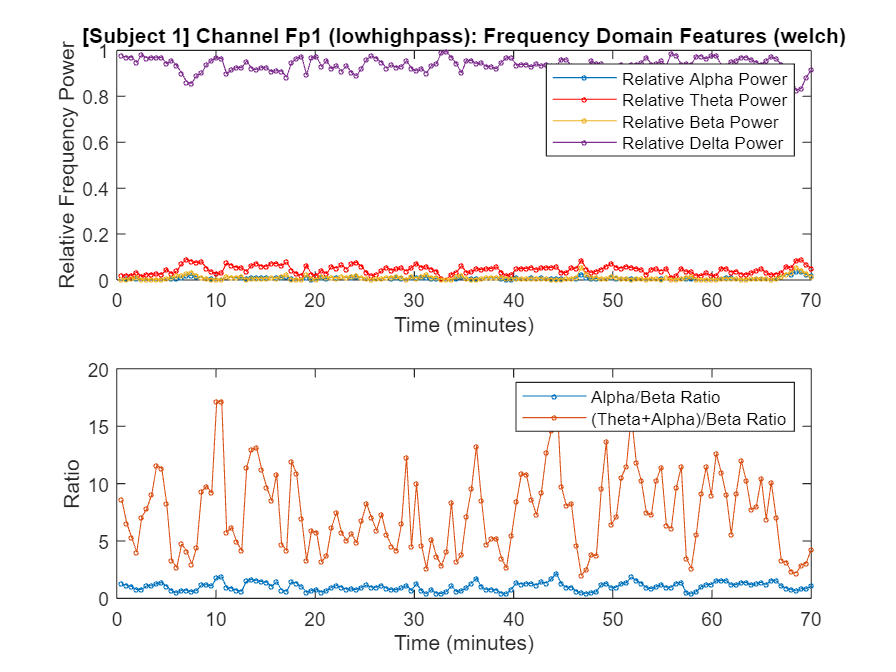

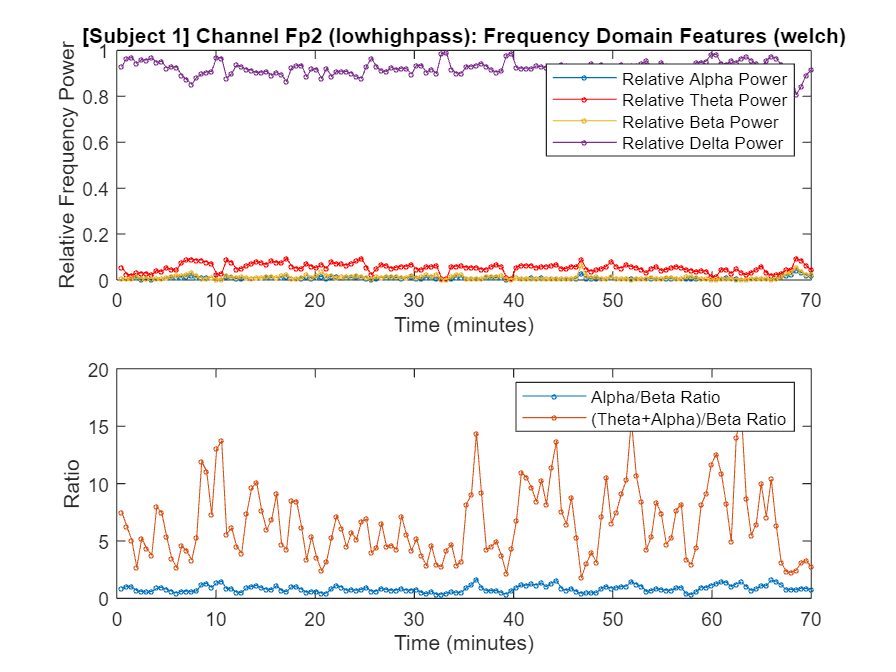

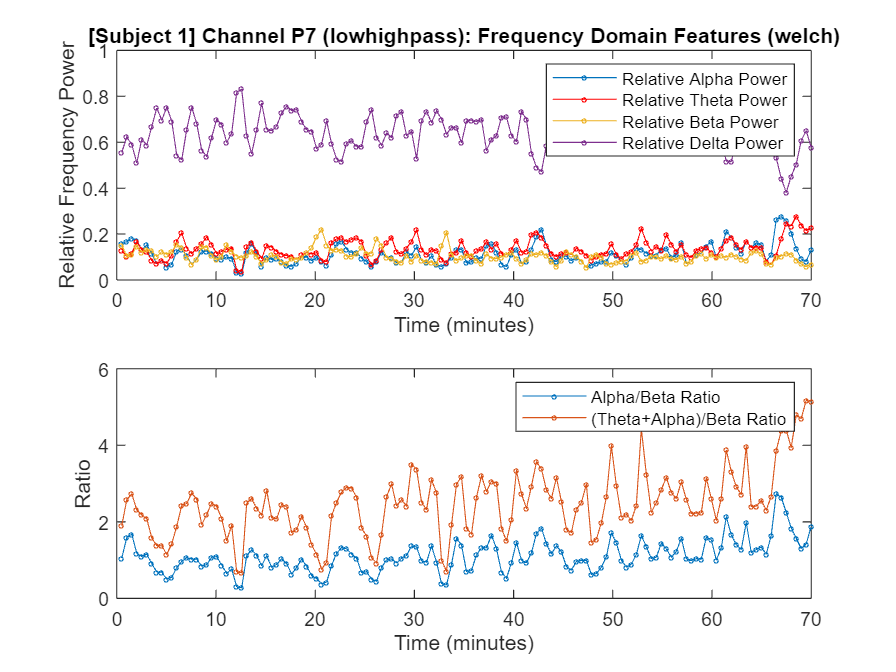

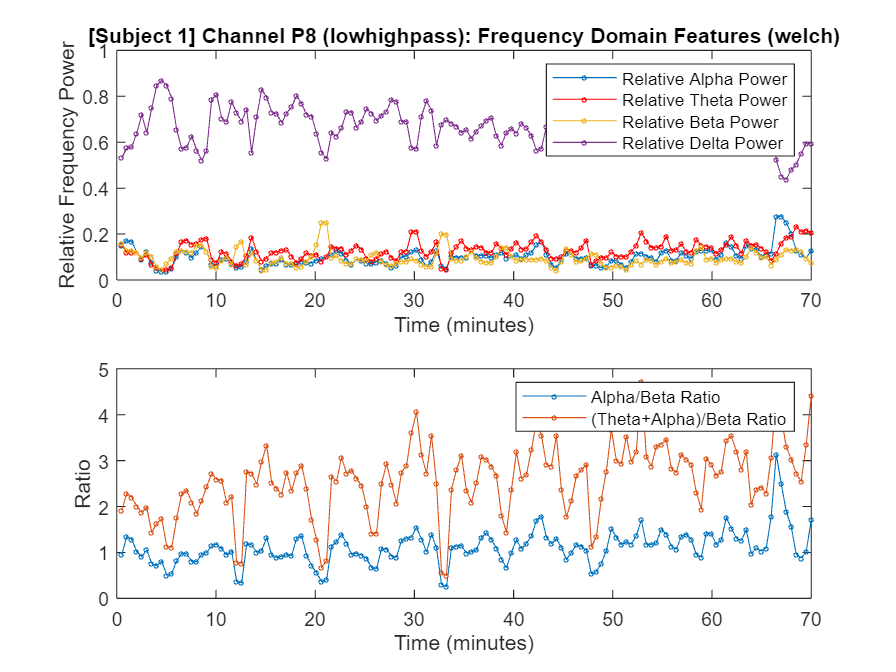

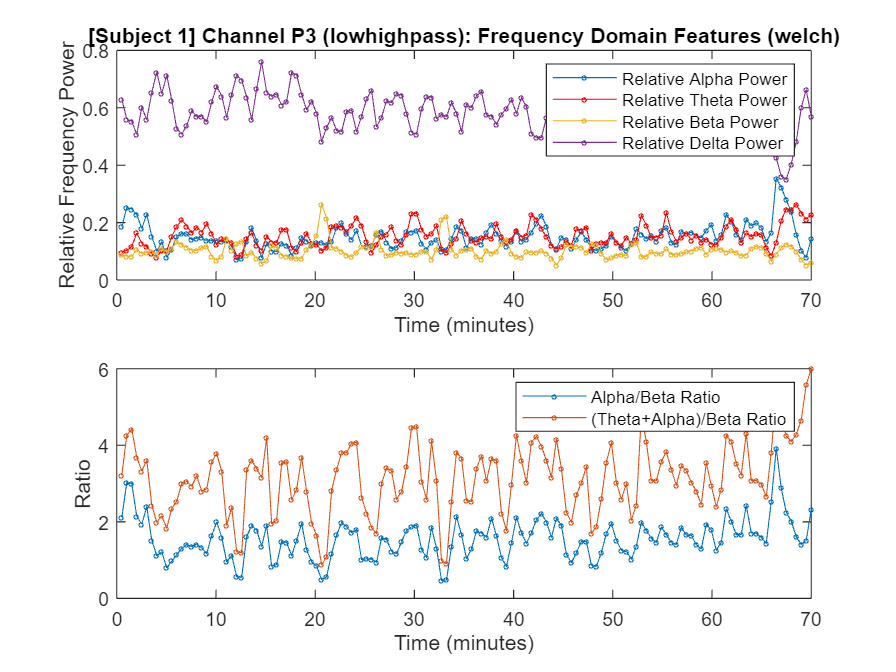

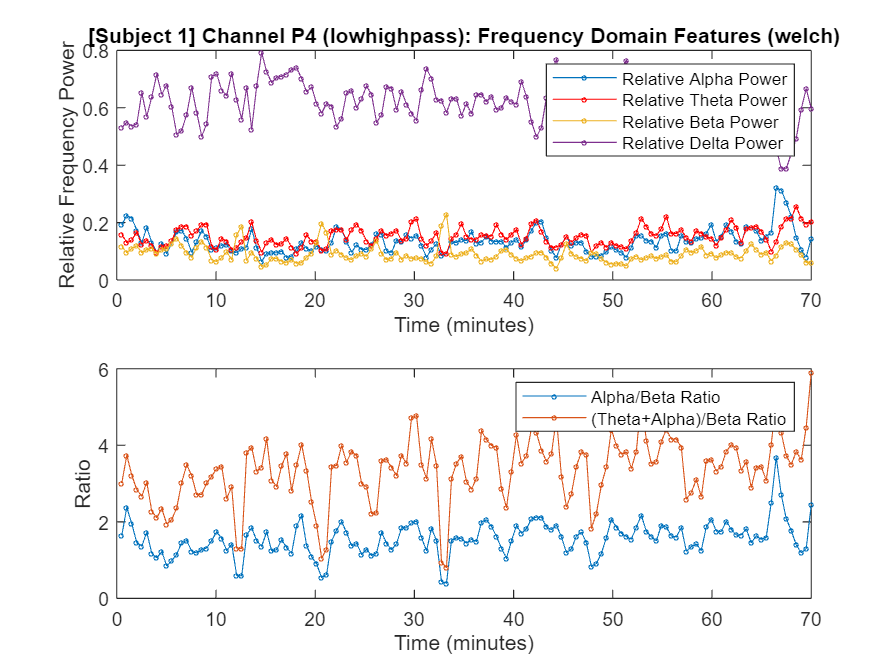

% Set Epoch Length and Overlapping
epochLength = 60; % length of each epoch in seconds
overlap = 0.5*epochLength; % overlap in seconds
numEpochs = floor((size(eeg_lowhighpass, 1) / fs - epochLength) / (epochLength - overlap)) + 1;

% Create Struct to contain features of all epochs from all channels
FreqFeatures_Epoch_pxx = repmat(struct('Epoch', [], 'TotalPower', [], 'AlphaPower', [], ...
    'AlphaRelative', [], 'ThetaPower', [], 'ThetaRelative', [], 'BetaPower1', [], ...
    'BetaPower2', [], 'RBR', [], 'BetaPower', [], 'BetaRelative', [], 'DeltaPower', [], ...
    'DeltaRelative', [], 'AlphaBetaRatio', [], 'TA_BRatio', []), numEpochs, 1);

% Loop Through Each Channel and Each Epoch to Extract Features
% Loop Through Each Channel
for channelIdx = 1:length(channelName)
    channel = channelName{channelIdx};
    
    % Loop Through Each Epoch
    for epoch = 1:numEpochs
        startTime = (epoch-1) * (epochLength - overlap); % Start time in seconds for the current epoch
        endTime = startTime + epochLength; % End time in seconds for the current epoch

        % Calculate the corresponding indices
        startIndex = round(startTime * fs) + 1;
        endIndex = round(endTime * fs);

        % Make sure endIndex does not exceed data length
        endIndex = min(endIndex, size(eeg_lowhighpass, 1));
    
        % Extract the relevant portion of the data for the current channel
        dataSegment = eeg_lowhighpass(startIndex:endIndex, channelIdx);

        % Calculate PSD Estimate
        [pxx, f] = pwelch(dataSegment, [], [], [], fs); % Welch's power PSD estimate
        % [pxx, f] = periodogram(dataSegment, [], [], fs); % Periodogram PSD estimate


    % calculate bandpower of each dataSegment
        PowerTotal = bandpower(pxx, f, FreqTotal, 'psd');
        PowerAlpha = bandpower(pxx, f, FreqAlpha, 'psd');
        PowerAlphaRelative = PowerAlpha / PowerTotal;
        PowerTheta = bandpower(pxx, f, FreqTheta, 'psd');
        PowerThetaRelative = PowerTheta / PowerTotal;
        PowerBeta1 = bandpower(pxx, f, [30 47], 'psd');
        PowerBeta2 = bandpower(pxx, f, [11 20], 'psd');
        RBR = PowerBeta1/PowerBeta2;
        PowerBeta = bandpower(pxx, f, FreqBeta, 'psd');
        PowerBetaRelative = PowerBeta / PowerTotal;
        PowerDelta = bandpower(pxx, f, FreqDelta, 'psd');
        PowerDeltaRelative = PowerDelta / PowerTotal;
        PowerAlphaBeta = PowerAlpha/PowerBeta;
        PowerTA_BRatio = (PowerTheta + PowerAlpha)/PowerBeta;

    % Store in struct
        FreqFeatures_Epoch_pxx(epoch, channelIdx).Epoch = epoch;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).TotalPower = PowerTotal;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).AlphaPower = PowerAlpha;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).AlphaRelative = PowerAlphaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).ThetaPower = PowerTheta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).ThetaRelative = PowerThetaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaPower1 = PowerBeta1;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaPower2 = PowerBeta2;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).RBR = RBR;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaPower = PowerBeta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).BetaRelative = PowerBetaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).DeltaPower = PowerDelta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).DeltaRelative = PowerDeltaRelative;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).AlphaBetaRatio = PowerAlphaBeta;
        FreqFeatures_Epoch_pxx(epoch, channelIdx).TA_BRatio = PowerTA_BRatio;

    end

    % Create Plot for relative power features of 1 channel
    % all features in 1 plot
    figure;
    subplot(2,1,1);
    TimeIndex = [FreqFeatures_Epoch_pxx(:, channelIdx).Epoch]*70/numEpochs;
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).AlphaRelative], '-o', 'MarkerSize', 2, 'DisplayName', 'Relative Alpha Power');
    hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).ThetaRelative], '-ro', 'MarkerSize', 2, 'MarkerEdgeColor', 'r', 'DisplayName', 'Relative Theta Power');
    hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).BetaRelative], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'Relative Beta Power');
    hold on
    % plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).RBR], '-go', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'RBR');
    % hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).DeltaRelative], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'Relative Delta Power');
    
    legend;
    xlabel('Time (minutes)');
    ylabel('Relative Frequency Power');
    title(sprintf('[Subject %d] Channel %s (%s): Frequency Domain Features (welch)', subject, channel, 'lowhighpass'));

    subplot(2,1,2);
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).AlphaBetaRatio], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', 'Alpha/Beta Ratio');
    hold on
    plot(TimeIndex, [FreqFeatures_Epoch_pxx(:, channelIdx).TA_BRatio], '-o', 'MarkerSize', 2, 'MarkerEdgeColor', 'auto', 'DisplayName', '(Theta+Alpha)/Beta Ratio');

    legend;
    xlabel('Time (minutes)');
    ylabel('Ratio');
end



FreqFeatures_Epoch_pxx_lowhighpass = FreqFeatures_Epoch_pxx

FreqFeatures_Epoch_pxx_lowhighpass = 139×12 struct array with fields:
    Epoch
    TotalPower
    AlphaPower
    AlphaRelative
    ThetaPower
    ThetaRelative
    BetaPower1
    BetaPower2
    RBR
    BetaPower
    BetaRelative
    DeltaPower
    DeltaRelative
    AlphaBetaRatio
    TA_BRatio


# **PREPARE DATA FOR MODEL DEVELOPMENT**

**Load EEG & ECG features**

% Load EEG data struct
EEG_features = FreqFeatures_Epoch_pxx_lowhighpass;

% Load ECG data struct
ECG_features = EpochDataHRV_corrected;

**export data to work in python**

% save('C:/Users/Natchira/Documents/M.eng (from hp)/Thesis/OpenViBE/EEG_ECG_Features.mat', "EEG_features", "ECG_features");
save(sprintf('C:/Users/Natchira/Documents/M.Eng/Class - Semester 2/EGBE601 Medical Signal Processing/Final_Project/dataset/EEG_ECG_Features_subject%d.mat', subject), "EEG_features", "ECG_features");

# **FUNCTION**

function indicesToEdit = ToEdit(filePath, subject)
    index_range = 'A:A';
    newValue_range = 'C:C';

    % Step 1: Edit
        % Read indices to edit
    index_table = readtable(filePath, 'Sheet', subject, 'Range', index_range, 'ReadVariableNames', false, 'TextType', 'string');
    index_array = table2array(index_table);
    index_array = index_array(~isnan(index_array)); % Filter out non-numeric
    
        % Read new values
    newValue_table = readtable(filePath, 'Sheet', subject, 'Range', newValue_range, 'ReadVariableNames', false, 'TextType', 'string');
    newValue_array = table2array(newValue_table);
    newValue_array = newValue_array(~isnan(newValue_array)); % Filter out non-numeric
    
    indicesToEdit = struct('index', index_array, 'newValue', newValue_array);
end

function indicesToDelete = ToDelete(filePath, subject)
    index_range = 'D:D';

    % Step 2: Delete
    index_table = readtable(filePath, 'Sheet', subject, 'Range', index_range, 'ReadVariableNames', false, 'TextType', 'string');
    % Convert to array and remove missing or non-numeric
    index_array = table2array(index_table);
    index_array = index_array(~isnan(index_array)); % Remove NaN values
    indicesToDelete = index_array; % Assuming all values are numeric at this point
end

function indicesToAdd = ToAdd(filePath, subject)
    newValue_range = 'F:F';

    % Step 3: Add
    newValue_table = readtable(filePath, 'Sheet', subject, 'Range', newValue_range, 'ReadVariableNames', false, 'TextType', 'string');
    newValue_array = table2array(newValue_table);
    
    if isnumeric(newValue_array) == 0
        indicesToAdd = [];
    else
        newValue_array = newValue_array(~isnan(newValue_array)); % Filter out non-numeric
        indicesToAdd = newValue_array';
    end
end

function correct_rpeak_time = RpeakCorrection(original_rpeak_time, filePath, subject)
    indicesToEdit = ToEdit(filePath, subject);
    indicesToDelete = ToDelete(filePath, subject);
    indicesToAdd = ToAdd(filePath, subject);

    correct_rpeak_time = original_rpeak_time;
    % Step 1: Edit
    for i = 1:length(indicesToEdit)
        correct_rpeak_time(indicesToEdit(i).index) = indicesToEdit(i).newValue;
    end

    % Step 2: Delete
    correct_rpeak_time(indicesToDelete) = [];

    % Step 3: Add
    correct_rpeak_time = [correct_rpeak_time, indicesToAdd];
    correct_rpeak_time = sort(correct_rpeak_time);
end
